# COTS Ensemble Live Script 18

## Load Data

load matlabCOTSEnsembleGithubP1.mat
load matlabCOTSEnsembleGithubP2.mat
load matlabCOTSEnsembleGithubP3.mat
load matlabCOTSEnsembleGithubP4.mat
load matlabCOTSEnsembleGithubP5.mat
load matlabCOTSEnsembleGithubP6.mat
load matlabCOTSEnsembleGithubP7.mat
load matlabCOTSEnsembleGithubP8.mat

## Set Interpreter

setInterpLatex()

## Contents

Checking All Matrices But SLIM

Adressing Issues With SLIM Structs

Checking SLIM Matrices

Pairwise Differences Part 2

## Assumptions

% need to reform the damn pDistsM variable because github but replace the g
% with an sh won't allow me to upload variables above a certain size
pDistsM = squareform(pdist(centroids));
conMatGlobNoNans = replaceNaNs(conMatGlobal, 0);

## Outbreak to Non-Outbreak Reefs Transfer

% let's make some masks so that my life is easier
outbrReefs = outbreakDataMatlab.outbreak == 1;
nonOutbrReefs = outbreakDataMatlab.outbreak == 0;
obsReefs = (outbreakDataMatlab.outbreak == 0) ...
    + (outbreakDataMatlab.outbreak == 1) > 0;

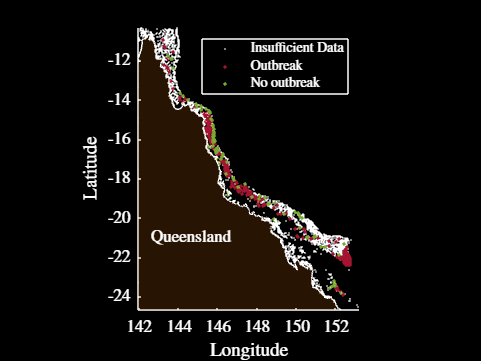

% I guess we can just mask out the nans? and look at the densities of
% outbreaking vs non-outbreaking reefs?

% idk, first let's look at the outbreaking vs non-outbreaking reefs
figure
hold on
plot(centroidsLL(:, 1), centroidsLL(:, 2), 'k.', 'MarkerSize', 2)
plot(centroidsLL(outbrReefs, 1), centroidsLL(outbrReefs, 2), '.', ...
    'color', getColour('r'), 'MarkerSize', 8)
plot(centroidsLL(nonOutbrReefs, 1), centroidsLL(nonOutbrReefs, 2), '.', ...
    'color', getColour('g'), 'MarkerSize', 8)
axis equal
plotQldOutline(qldOutline)
axis(gbrBoundaryLL)
legend("Insufficient Data", "Outbreak", "No outbreak")
xlabel("Longitude")
ylabel("Latitude")
setFontSize(14)
lightFig()
saveFig("outbreaksSpatially")
darkFig()
saveFig("outbreaksSpatiallyDM")

% alright - I need to calculate the sampling intensity for each reef
reefAreas = [gbrShapeLL.Shape_Area]';
adjMat110km = pDistsM < 110 * 1000;
sampleIntensity = adjMat110km * (obsReefs .* reefAreas);
reefDensity = adjMat110km * reefAreas;

% set any zeros in sampleIntensity to NaNs
sampleIntensity(sampleIntensity == 0) = NaN;

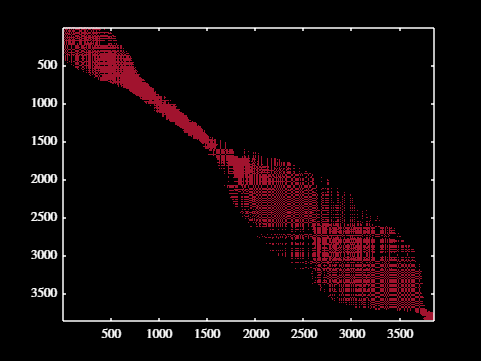

% double check that the adjacency matrix is making sense
figure
imagesc(adjMat110km(sortLat3861, sortLat3861))
colormap(myColourMap())
darkFig()

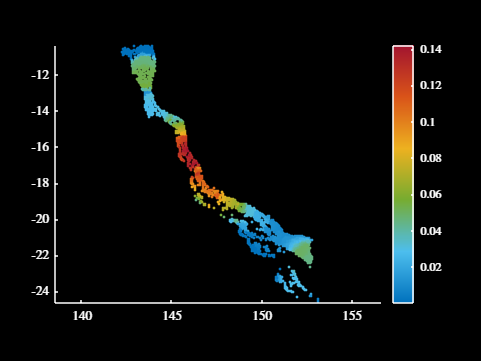

% let's plot the sampling intensity so that I can eyeball it
figure
scatter(centroidsLL(:, 1), centroidsLL(:, 2), 4, sampleIntensity, ...
    "filled")
colormap(myColourMap("dmTurbo"))
axis equal
colorbar()
darkFig()

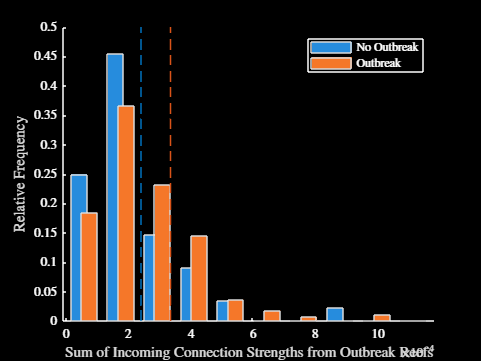

% we can then do a number of things here - we could count the number of
% connections first, which would make life a bit easier

% we could then also consider the sum of the connection strengths, which
% will be more effective

% screw it - let's just do the sum of the connection strengths
conStrengthsInSum = reefDensity .* (conMatGlobal * ...
    (outbrReefs .* reefAreas)) ./ sampleIntensity;
var1 = linspace(0, max(conStrengthsInSum), 21);
var1 = linspace(0, 0.1 * max(conStrengthsInSum), 11);
var2 = (var1(1:end-1) + var1(2:end)) / 2;
figure
hold on
var3 = histcounts(conStrengthsInSum(outbrReefs), var1);
var3 = var3 / sum(var3);
var4 = histcounts(conStrengthsInSum(nonOutbrReefs), var1);
var4 = var4 / sum(var4);
var5 = [var4', var3'];
bar(var2, var5, 1.5, 'grouped');
xline(mean(conStrengthsInSum(outbrReefs)), '--', 'Color', ...
    getColour('o'), 'Alpha', 1, 'LineWidth', 1)
xline(mean(conStrengthsInSum(nonOutbrReefs)), '--', 'Color', ...
    getColour('b'), 'Alpha', 1, 'LineWidth', 1)
legend("No Outbreak", "Outbreak")
ylabel("Relative Frequency")
xlabel("Sum of Incoming Connection Strengths from Outbreak Reefs")
lightFig()
saveFig("incomingConnectionsSum")
darkFig()
saveFig("incomingConnectionsSumDM")

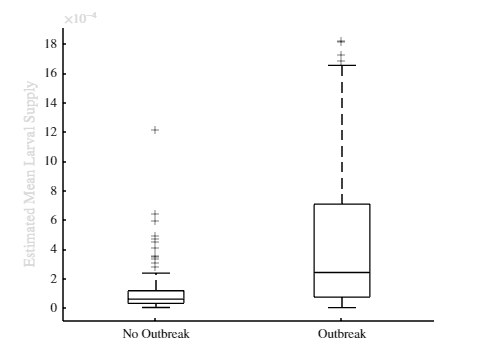

% let's do the same as the above but using mean cots densities
conStrengthsInSum = reefDensity .* (conMatGlobal * ...
    (replaceNaNs(outbreakDataMatlab.cotsPerTowMean, 0) ...
    .* reefAreas)) ./ sampleIntensity;

% let's also do a boxplot
var1 = [conStrengthsInSum(nonOutbrReefs); ...
    conStrengthsInSum(outbrReefs)];
var2 = [zeros(size(conStrengthsInSum(nonOutbrReefs))); ...
    ones(size(conStrengthsInSum(outbrReefs)))];
figure
boxplot(var1, var2, 'colors', getColour('k'), 'Symbol', 'k+')
set(gca, 'TickLabelInterpreter', 'Latex')
xticklabels(["No Outbreak", "Outbreak"])
ylabel("Estimated Mean Larval Supply")
box off
lightFig()
saveFig("estimatedMeanLarvSuppBox")

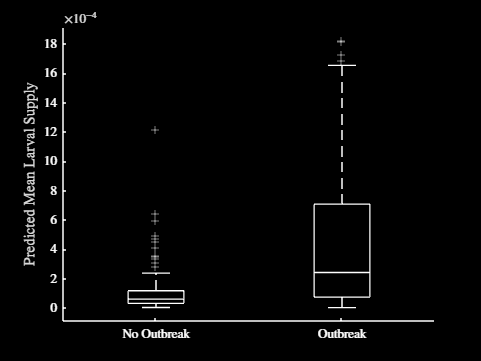


figure
boxplot(var1, var2, 'colors', 'w', 'Symbol', 'w+')
set(gca, 'TickLabelInterpreter', 'Latex')
xticklabels(["No Outbreak", "Outbreak"])
ylabel("Predicted Mean Larval Supply")
box off
darkFig()
saveFig("estimatedMeanLarvSuppBoxDM")

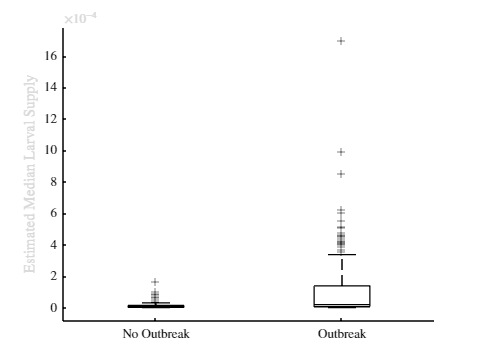

% let's do the same as the above but with the median rather than mean
conStrengthsInSum = reefDensity .* (conMatGlobNoNans' * ...
    (replaceNaNs(outbreakDataMatlab.cotsPerTowMedian, 0) ...
    .* reefAreas)) ./ sampleIntensity;

% let's also do a boxplot
var1 = [conStrengthsInSum(nonOutbrReefs); ...
    conStrengthsInSum(outbrReefs)];
var2 = [zeros(size(conStrengthsInSum(nonOutbrReefs))); ...
    ones(size(conStrengthsInSum(outbrReefs)))];
figure
boxplot(var1, var2, 'colors', getColour('k'), 'Symbol', 'k+')
set(gca, 'TickLabelInterpreter', 'Latex')
xticklabels(["No Outbreak", "Outbreak"])
ylabel("Estimated Median Larval Supply")
box off
lightFig()
saveFig("estimatedMedianLarvSuppBox")

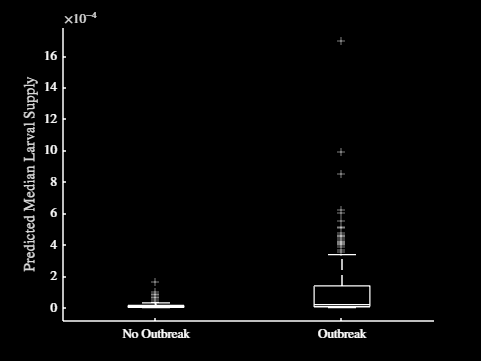


figure
boxplot(var1, var2, 'colors', 'w', 'Symbol', 'w+')
set(gca, 'TickLabelInterpreter', 'Latex')
xticklabels(["No Outbreak", "Outbreak"])
ylabel("Predicted Median Larval Supply")
box off
darkFig()
saveFig("estimatedMedianLarvSuppBoxDM")

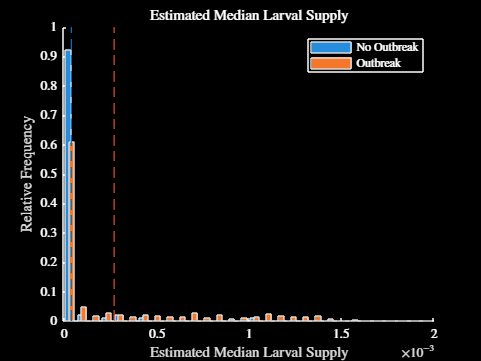

% let's do the same as the above but for number of connections
conStrengthsInSum = reefDensity .* (conMatGlobal * ...
    (replaceNaNs(outbreakDataMatlab.cotsPerTowMedian, 0) ...
    .* reefAreas)) ./ sampleIntensity;
var1 = linspace(0, max(conStrengthsInSum), 31);
var1 = linspace(0, 2 * 10^-3, 31);
% var1 = linspace(0, 0.1 * max(conStrengthsInSum), 11);
% var1 = linspace(0, 2 * 10^-3, 11);
% var1 = linspace(0, 2 * 10^-3, 11);
var2 = (var1(1:end-1) + var1(2:end)) / 2;
figure
hold on
var3 = histcounts(conStrengthsInSum(outbrReefs), var1);
var4 = histcounts(conStrengthsInSum(nonOutbrReefs), var1);
var5 = [(var4/ sum(var4))', (var3 / sum(var3))'];
bar(var2, var5, 1.5, 'grouped');
xline(mean(conStrengthsInSum(outbrReefs)), '--', 'Color', ...
    getColour('o'), 'Alpha', 1, 'LineWidth', 1)
xline(mean(conStrengthsInSum(nonOutbrReefs)), '--', 'Color', ...
    getColour('b'), 'Alpha', 1, 'LineWidth', 1)
legend("No Outbreak", "Outbreak")
ylabel("Relative Frequency")
xlabel("Estimated Median Larval Supply")
title("Estimated Median Larval Supply")

darkFig()
saveFig("estimatedMedianLarvSuppDM")
lightFig()
saveFig("estimatedMedianLarvSupp")
darkFig()

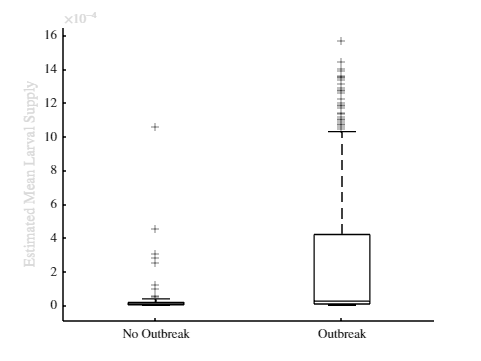


% let's also do a boxplot
var1 = [conStrengthsInSum(nonOutbrReefs); ...
    conStrengthsInSum(outbrReefs)];
var2 = [zeros(size(conStrengthsInSum(nonOutbrReefs))); ...
    ones(size(conStrengthsInSum(outbrReefs)))];
figure
boxplot(var1, var2, 'colors', getColour('k'), 'Symbol', 'k+')
set(gca, 'TickLabelInterpreter', 'Latex')
xticklabels(["No Outbreak", "Outbreak"])
ylabel("Estimated Mean Larval Supply")
box off
lightFig()
saveFig("estimatedMeanLarvSuppBox")

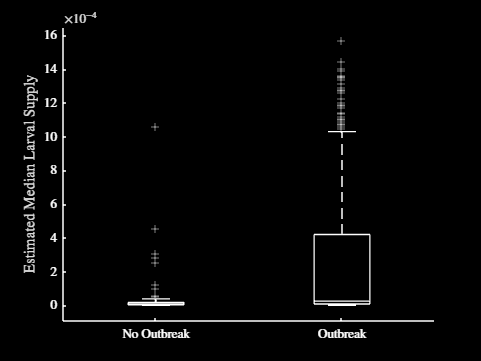


figure
boxplot(var1, var2, 'colors', 'w', 'Symbol', 'w+')
set(gca, 'TickLabelInterpreter', 'Latex')
xticklabels(["No Outbreak", "Outbreak"])
ylabel("Estimated Median Larval Supply")
box off
darkFig()
saveFig("estimatedMeanLarvSuppBoxDM")

## Differentiating outbreak and non-outbreak reefs

% alright, now need to load in the outbreaking data
outbreakDataMatlab = readtable("../Data/Matlab Transfer/outbreakDataMatlab");
outbreakData = readtable("../Data/Matlab Transfer/outbreakData");

% let's make some masks so that my life is easier
outbrReefs = outbreakDataMatlab.outbreak == 1;
nonOutbrReefs = outbreakDataMatlab.outbreak == 0;
obsReefs = (outbreakDataMatlab.outbreak == 0) ...
    + (outbreakDataMatlab.outbreak == 1) > 0;

% ok, need to first send over the predicted larval supply for the reefs
reefDensity = adjMat110km * reefAreas;
conStrengthsInSum = reefDensity .* (conMatGlobal * ...
    (replaceNaNs(outbreakDataMatlab.cotsPerTowMean, 0) ...
    .* reefAreas)) ./ sampleIntensity;
writematrix(conStrengthsInSum, "../Data/Matlab Transfer/larvSuppPred.csv")

sortLat3861

sortLat3861 =         3467
        3474
        3473
        3475
        3476
        3477
        3478
        3487
        3488
        3486


writematrix(sortLat3861, "../Data/Matlab Transfer/sortLat3861.csv")

% let's do the figures but redo them usign mean cots densities from more
% reefs
meanCotsData = readtable("../Data/Matlab Transfer/meanCotsData");
meanCotsDataMatlab = readtable("../Data/Matlab Transfer/meanCotsDataMatlab");

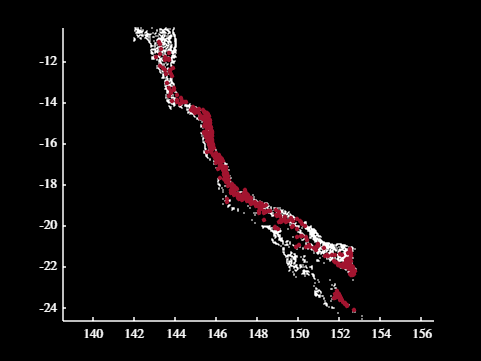

% alright - I need to calculate the sampling intensity for each reef
obsReefs = ~isnan(meanCotsDataMatlab.cotsPerTowMean);
reefAreas = [gbrShapeLL.Shape_Area]';
adjMat110km = pDistsM < 110 * 1000;
sampleIntensity = adjMat110km * (obsReefs .* reefAreas);
reefDensity = adjMat110km * reefAreas;

% set any zeros in sampleIntensity to NaNs
sampleIntensity(sampleIntensity == 0) = NaN;

% let's visualise the reefs that we have
figure
hold on
plot(centroidsLL(:, 1), centroidsLL(:, 2) ,'k.', 'MarkerSize', 2)
plot(centroidsLL(obsReefs, 1), centroidsLL(obsReefs, 2) ,'.', 'color', ...
    getColour('r'), 'MarkerSize', 10)
axis equal
darkFig()

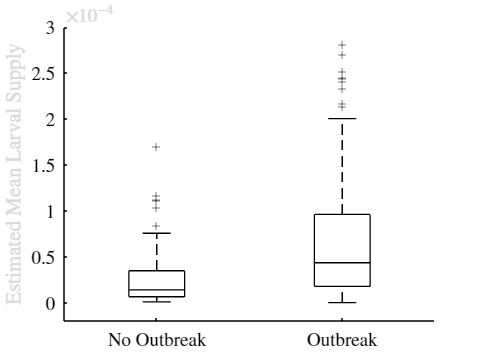

% let's now recalculate the larval supply estimate
% let's do the same as the above but using mean cots densities
conMatGlobNoNans = conMatGlobal;
conMatGlobNoNans(isnan(conMatGlobNoNans)) = 0;
conStrengthsInSum = reefDensity .* (conMatGlobNoNans' * ...
    (replaceNaNs(meanCotsDataMatlab.cotsPerTowMean, 0) ...
    .* reefAreas)) ./ sampleIntensity;

% let's also do a boxplot
var1 = [conStrengthsInSum(nonOutbrReefs); ...
    conStrengthsInSum(outbrReefs)];
var2 = [zeros(size(conStrengthsInSum(nonOutbrReefs))); ...
    ones(size(conStrengthsInSum(outbrReefs)))];
figure
boxplot(var1, var2, 'colors', getColour('k'), 'Symbol', 'k+')
% ylim([-0.2 * 10^-4, 10 * 10^-4])
ylim([-0.2 * 10^-4, 3 * 10^-4]) 
set(gca, 'TickLabelInterpreter', 'Latex')
xticklabels(["No Outbreak", "Outbreak"])
ylabel("Estimated Mean Larval Supply", 'interpreter', 'latex')
box off
setFontSize(16)
lightFig()
saveFig("estimatedMeanLarvSuppBox")

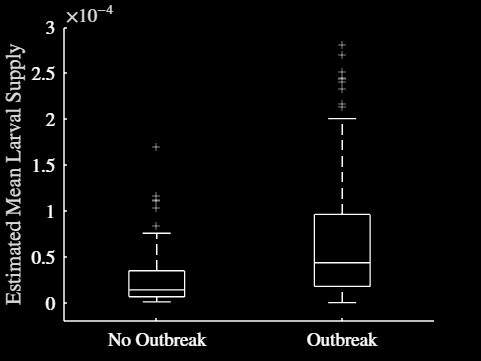


figure
boxplot(var1, var2, 'colors', 'w', 'Symbol', 'w+')
set(gca, 'TickLabelInterpreter', 'Latex')
xticklabels(["No Outbreak", "Outbreak"])
% ylim([-0.2 * 10^-4, 10 * 10^-4]) 
ylim([-0.2 * 10^-4, 3 * 10^-4]) 
ylabel("Estimated Mean Larval Supply", 'interpreter', 'latex')
box off
setFontSize(16)
darkFig()
saveFig("estimatedMeanLarvSuppBoxDM")

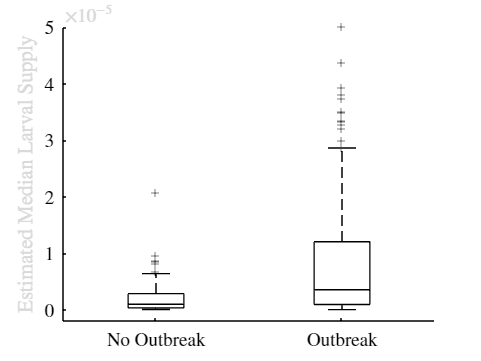

% let's now recalculate the larval supply estimate
% let's do the same as the above but using mean cots densities
conMatGlobNoNans = conMatGlobal;
conMatGlobNoNans(isnan(conMatGlobNoNans)) = 0;
conStrengthsInSum = reefDensity .* (conMatGlobNoNans' * ...
    (replaceNaNs(meanCotsDataMatlab.cotsPerTowMedian, 0) ...
    .* reefAreas)) ./ sampleIntensity;

% let's also do a boxplot
var1 = [conStrengthsInSum(nonOutbrReefs); ...
    conStrengthsInSum(outbrReefs)];
var2 = [zeros(size(conStrengthsInSum(nonOutbrReefs))); ...
    ones(size(conStrengthsInSum(outbrReefs)))];
figure
boxplot(var1, var2, 'colors', getColour('k'), 'Symbol', 'k+')
% ylim([-0.2 * 10^-4, 10 * 10^-4])
ylim([-0.2 * 10^-5, 5 * 10^-5]) 
set(gca, 'TickLabelInterpreter', 'Latex')
xticklabels(["No Outbreak", "Outbreak"])
ylabel("Estimated Median Larval Supply", 'interpreter', 'latex')
box off
setFontSize(16)
lightFig()
saveFig("estimatedMedianLarvSuppBox")

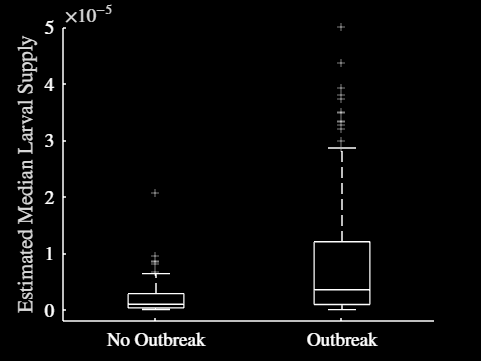


figure
boxplot(var1, var2, 'colors', 'w', 'Symbol', 'w+')
set(gca, 'TickLabelInterpreter', 'Latex')
xticklabels(["No Outbreak", "Outbreak"])
% ylim([-0.2 * 10^-4, 10 * 10^-4]) 
ylim([-0.2 * 10^-5, 5 * 10^-5]) 
ylabel("Estimated Median Larval Supply", 'interpreter', 'latex')
box off
setFontSize(16)
darkFig()
saveFig("estimatedMedianLarvSuppBoxDM")

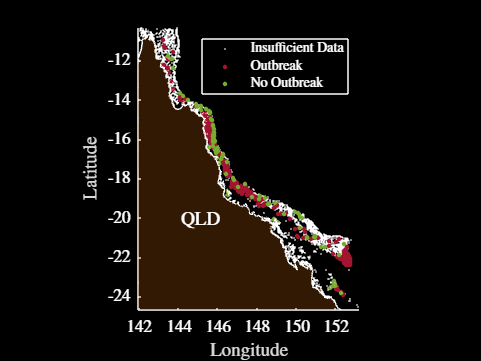

% make a nice plot of the outbreaking vs non-outbreaking reefs
figure
hold on
plot(centroidsLL(:, 1), centroidsLL(:, 2), 'k.', 'MarkerSize', 2)
plot(centroidsLL(outbrReefs, 1), centroidsLL(outbrReefs, 2), '.', ...
    'color', getColour('r'), 'MarkerSize', 10)
plot(centroidsLL(nonOutbrReefs, 1), centroidsLL(nonOutbrReefs, 2), '.', ...
    'color', getColour('g'), 'MarkerSize', 10)
axis equal
plotShapes(qldOutline, 'colour', getColour('br'), 'fill', 'fill', ...
    'alpha', 0.25)
plotShapes(qldOutline, 'colour', 'k')
axis(gbrBoundaryLL)
legend("Insufficient Data", "Outbreak", "No Outbreak")
xlabel("Longitude")
ylabel("Latitude")
text(144, -20, "QLD", 'FontSize', 14)
setFontSize(14)
lightFig()
saveFig("outbreaksSpatially")
darkFig()
saveFig("outbreaksSpatiallyDM")

## Curve Fitting Figures

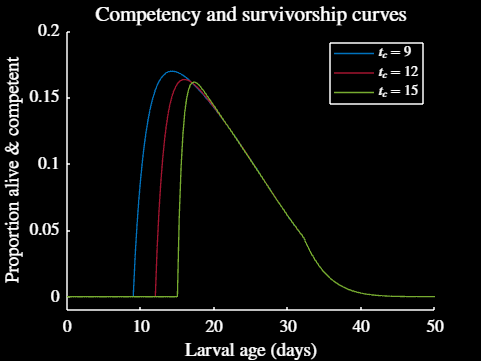

% need to redo the got damn survivorship and competency curve visualisation
% stuff so that the actual data is behind the curves
tVec = linspace(0, 50, 201);
figure
hold on

% now plot the curves
load("../Data/competencySurvivorshipData/compSurvAll.mat")
probVec = compFuncWeibExp(tVec, paramsStructComp) ...
    .* survFuncExpWeibWeib(tVec, paramsStructSurv);
plot(tVec, probVec, '-', "Color", getColour('b'), ...
    'LineWidth', 1)
load("../Data/competencySurvivorshipData/compSurvTc12.mat")
probVec = compFuncWeibExp(tVec, paramsStructComp) ...
    .* survFuncExpWeibWeib(tVec, paramsStructSurv);
plot(tVec, probVec, '-', "Color", getColour('r'), ...
    'LineWidth', 1)
load("../Data/competencySurvivorshipData/compSurvTc15.mat")
probVec = compFuncWeibExp(tVec, paramsStructComp) ...
    .* survFuncExpWeibWeib(tVec, paramsStructSurv);
plot(tVec, probVec, '-', "Color", getColour('g'), ...
    'LineWidth', 1)
legend("$t_c = 9$", "$t_c = 12$", "$t_c = 15$")
ylim([-0.01, 0.2])
xlabel('Larval age (days)')
ylabel('Proportion alive \& competent')
title('Competency and survivorship curves')
setFontSize(14)
lightFig()
saveFig("compSurvCurves")
darkFig()
saveFig("compSurvCurvesDM")

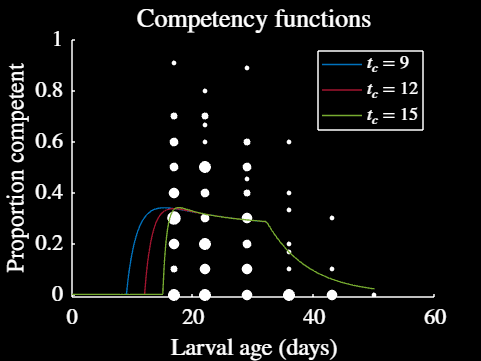

% alright let's try and overlay the data points
% now plot the curves
figure
hold on
[var1, var2] = uniqueAndCount(compDataPerc, "rows");
scatter(var1(:, 1), var1(:, 2), 4 * (0.2 * var2.^2 + 3 * var2), 'k', 'filled')
load("../Data/competencySurvivorshipData/compSurvAll.mat")
probVec = compFuncWeibExp(tVec, paramsStructComp);
plot(tVec, probVec, '-', "Color", getColour('b'), ...
    'LineWidth', 1)
load("../Data/competencySurvivorshipData/compSurvTc12.mat")
probVec = compFuncWeibExp(tVec, paramsStructComp);
plot(tVec, probVec, '-', "Color", getColour('r'), ...
    'LineWidth', 1)
load("../Data/competencySurvivorshipData/compSurvTc15.mat")
probVec = compFuncWeibExp(tVec, paramsStructComp);
plot(tVec, probVec, '-', "Color", getColour('g'), ...
    'LineWidth', 1)
legend("", "$t_c = 9$", "$t_c = 12$", "$t_c = 15$")
ylim([-0.01, 1])
xlabel('Larval age (days)')
ylabel('Proportion competent')
title('Competency functions')
setFontSize(18)
lightFig()
saveFig("compCurves")
[var1, var2] = uniqueAndCount(compDataPerc, "rows");
scatter(var1(:, 1), var1(:, 2), 4 * (0.2 * var2.^2 + 3 * var2), 'w', 'filled')
load("../Data/competencySurvivorshipData/compSurvAll.mat")
probVec = compFuncWeibExp(tVec, paramsStructComp);
plot(tVec, probVec, '-', "Color", getColour('b'), ...
    'LineWidth', 1)
load("../Data/competencySurvivorshipData/compSurvTc12.mat")
probVec = compFuncWeibExp(tVec, paramsStructComp);
plot(tVec, probVec, '-', "Color", getColour('r'), ...
    'LineWidth', 1)
load("../Data/competencySurvivorshipData/compSurvTc15.mat")
probVec = compFuncWeibExp(tVec, paramsStructComp);
plot(tVec, probVec, '-', "Color", getColour('g'), ...
    'LineWidth', 1)
legend("", "$t_c = 9$", "$t_c = 12$", "$t_c = 15$")
darkFig()
saveFig("compCurvesDM")

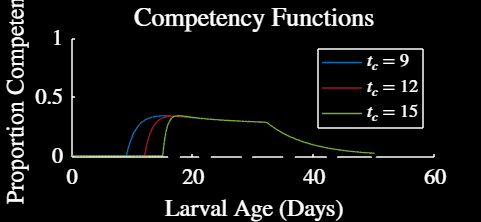

figure
figResize(0.8, 1.3)
hold on
[var1, var2] = uniqueAndCount(compDataPerc, "rows");
scatter(var1(:, 1), var1(:, 2), 4 * (0.2 * var2.^2 + 3 * var2), 'k', 'filled')
load("../Data/competencySurvivorshipData/compSurvAll.mat")
probVec = compFuncWeibExp(tVec, paramsStructComp);
plot(tVec, probVec, '-', "Color", getColour('b'), ...
    'LineWidth', 1)
load("../Data/competencySurvivorshipData/compSurvTc12.mat")
probVec = compFuncWeibExp(tVec, paramsStructComp);
plot(tVec, probVec, '-', "Color", getColour('r'), ...
    'LineWidth', 1)
load("../Data/competencySurvivorshipData/compSurvTc15.mat")
probVec = compFuncWeibExp(tVec, paramsStructComp);
plot(tVec, probVec, '-', "Color", getColour('g'), ...
    'LineWidth', 1)
legend("", "$t_c = 9$", "$t_c = 12$", "$t_c = 15$")
ylim([-0.01, 1])
xlabel('Larval Age (Days)')
ylabel('Proportion Competent')
title('Competency Functions')
setFontSize(18)
lightFig()
saveFig("compCurvesPres")
darkFig()

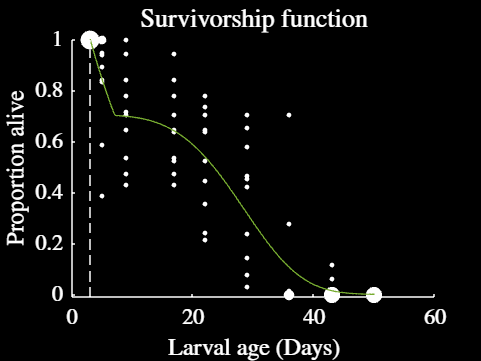

figure
% figResize(0.8, 1.3)
hold on
tVec = linspace(3, 50, 201);
[var1, var2] = uniqueAndCount(survDataDec, "rows");
scatter(var1(:, 1), var1(:, 2), 4 * (0.1 * var2.^2 + 3 * var2), 'k', 'filled')
xline(3, '--k')
load("../Data/competencySurvivorshipData/compSurvAll.mat")
probVec = survFuncWeibWeib(tVec, paramsStructSurv);
probVec = probVec / probVec(1);
plot(tVec, probVec, '-', "Color", getColour('g'), ...
    'LineWidth', 1)
ylim([-0.01, 1])
xlabel('Larval age (Days)')
ylabel('Proportion alive')
title('Survivorship function')
setFontSize(18)
lightFig()
saveFig("survCurve")
scatter(var1(:, 1), var1(:, 2), 4 * (0.2 * var2.^2 + 3 * var2), 'w', 'filled')
tVec = linspace(3, 50, 201);
probVec = survFuncWeibWeib(tVec, paramsStructSurv);
probVec = probVec / probVec(1);
plot(tVec, probVec, '-', "Color", getColour('g'), ...
    'LineWidth', 1)
darkFig()
saveFig("survCurvDM")

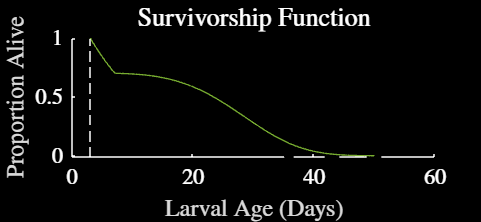

figure
figResize(0.8, 1.3)
hold on
tVec = linspace(3, 50, 201);
[var1, var2] = uniqueAndCount(survDataDec, "rows");
scatter(var1(:, 1), var1(:, 2), 4 * (0.1 * var2.^2 + 3 * var2), 'k', 'filled')
xline(3, '--k')
load("../Data/competencySurvivorshipData/compSurvAll.mat")
probVec = survFuncWeibWeib(tVec, paramsStructSurv);
probVec = probVec / probVec(1);
plot(tVec, probVec, '-', "Color", getColour('g'), ...
    'LineWidth', 1)
ylim([-0.01, 1])
xlabel('Larval Age (Days)')
ylabel('Proportion Alive')
title('Survivorship Function')
setFontSize(18)
lightFig()
saveFig("survCurvePres")
darkFig()